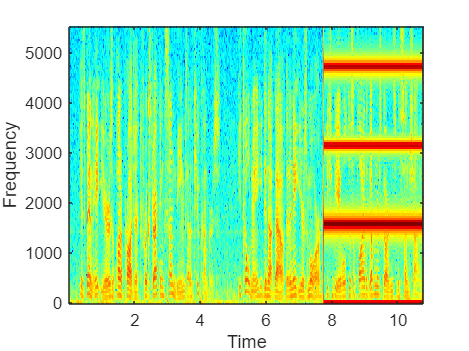

[xx, fs] = audioread('SunshineSquare.wav');
xx = xx';
figure(1)
specgram(xx, [], fs)


N = length(xx);
X = fft(xx);
X_mag = abs(X(1:floor(N/2)));  
f_axis = (0:floor(N/2)-1) * fs / N;


search_ranges = [1570 1620; 
                 3120 3170; 
                 4710 4760];

peak_freqs = zeros(1, size(search_ranges, 1));

for i = 1:size(search_ranges, 1)
    idx = find(f_axis >= search_ranges(i, 1) & f_axis <= search_ranges(i, 2));
    [~, max_idx] = max(X_mag(idx));
    peak_freqs(i) = f_axis(idx(max_idx));     
end

format long
disp('peak freqs ：');

peak freqs ：


disp(peak_freqs);

   1.0e+03 *

   1.574986772597862   3.149973545195723   4.724960317793585



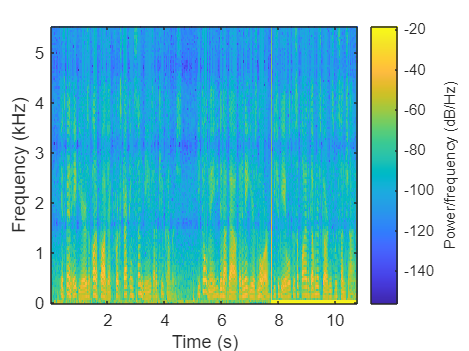



f1 = 1574.9868;
f2 = 3149.9735;
f3 = 4724.9603;

w1 = 2*pi*f1/fs;
w2 = 2*pi*f2/fs;
w3 = 2*pi*f3/fs;

A1 = -2*cos(w1);
hh1 = [1 A1 1]; 
A2 = -2*cos(w2);
hh2 = [1 A2 1];
A3 = -2*cos(w3);
hh3 = [1 A3 1];

hh_combined = conv(conv(hh1, hh2), hh3);
yy_combined = filter(hh_combined, 1, xx);

figure;
spectrogram(yy_combined, 256, [], [], fs, 'yaxis');


yy_combined = yy_combined / max(abs(yy_combined));
audiowrite('CleanedUp.wav', yy_combined, fs);

## Frequency Response of Combined Filter

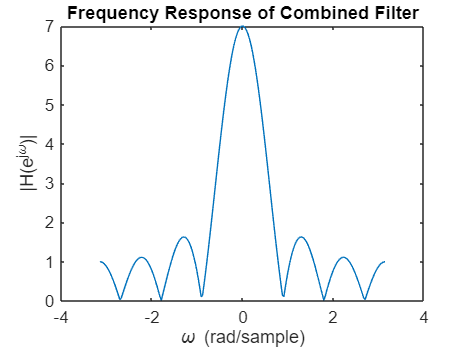

ww = -pi:pi/100:pi;
HH = freqz(hh_combined, 1, ww);

hh_combined = conv(conv(hh1, hh2), hh3);
ww = -pi:pi/100:pi;
HH = freqz(hh_combined, 1, ww);

figure;
plot(ww, abs(HH));
title('Frequency Response of Combined Filter');
xlabel('\omega (rad/sample)');
ylabel('|H(e^{j\omega})|');